# Classification of pathological conditions.

## 1] INTRODUCTION

Recent advances in neurodegenerative disease research underscore the growing urgency to develop effective treatments for these debilitating conditions, which collectively afflict over 55 million people worldwide that will almost double every 20 years, reaching 78 million in 2030 and 139 million in 2050 [1]. With aging populations worldwide, the burden of these diseases on healthcare systems is increasing, highlighting the critical need for innovative solutions.

The best way to treat these disorders is to detect them at an earlier stage. Many of these diseases are genetic; this enables machine learning algorithms to give inferences based on the patient’s medical records and history. Machine learning algorithms such as deep neural networks are also critical for the early identification of degenerative nerve diseases.

Due to recent advances in artificial intelligence, a significant help can come from the computational approaches targeting diagnosis and monitoring, e.g., *detection of disease onset, characterization of the disease, improvement of the differential diagnosis, quantification of the disease progression, tracking of the medication effects *[2]. 

These tasks can be automated or at least improved with the help of machine learning algorithm as demonstrated in a plathora of studies like the one conducted by Belić et al. [3], where the team has implemented ML algorithms for real-time remote monitoring in order to detect disease severity, record symptoms, and register a patient’s response to treatment. 

Other examples come from studies that used ML to differentiate between neurons of patients with AD and those with mild cognitive impairment (MCI), the precursor to AD ([4], [5]). Results of these studies allow researchers to identify biomarkers capable of predicting disease trajectory [5] and of explaining individual vulnerability or resilience to cognitive decline [4].

In parallel, in vitro models offer powerful tools for studying neurodegenerative diseases in a controlled laboratory environment. These models have evolved from early organotypic cultures to more sophisticated 3D systems derived from human embryonic stem cells (ESCs) and induced pluripotent stem cells (iPSCs) [6], [7]. Such models better mimic the complex cellular interactions observed in vivo, providing researchers with a platform to elucidate disease mechanisms, screen potential therapeutics, and explore cell replacement therapies.

The integration of machine learning algorithms with advanced in vitro models represents a significant step forward in neurodegenerative disease research. By combining computational analysis with experimental data, researchers can gain deeper insights into disease processes, identify novel therapeutic targets, and accelerate the development of effective treatments. Moreover, these approaches hold promise for personalized medicine, as they enable the identification of patient-specific disease characteristics and treatment responses, offering a multifaceted approach to tackling neurodegenerative diseases. 

By leveraging the power of artificial intelligence and stem cell technology, researchers are poised to make significant strides in understanding these complex disorders and ultimately improving patient outcomes.

**OBJECTIVE**: Classify and understand pathological conditions within in vitro 3D systems [Healty, Amyotrophich Lateral Sclerosis (ALS), Alzheimer’s disease (AD) and Parkinson’s disease (PD)] applying Supervised Learning models.

SL is the most commonly used way in ML-based diagnosis [8]. The main purpose of supervised ML model is to predict labels, or values, of unseen instances with their corresponding given attributes. The SL model can be viewed as a mapping from attributes to a label. A label of a data instance can be either a discrete value, or a class, or a representing number in a continuous space. If labels are classes, the ML task is a classification problem. The supervised learning fits to the purpose of diagnosis since diagnosis can be viewed as evaluation/prediction of patients with measured quantities.

## 2] DATASET

The file *"MEAdata.xls"* contains parameters extracted from cortical neuronal networks in vitro. It refers to neural networks cultured in laboratory settings outside of a living organism, specifically derived from cortical tissue.

Creating cortical neuronal networks in vitro involves isolating and culturing neurons from the cortex of an animal (often rodents) or, more recently, generating neurons from stem cells, such as induced pluripotent stem cells (iPSCs). These neurons are typically cultured on a substrate, such as a petri dish or multi-electrode array (MEA), allowing them to form connections and communicate with each other to resemble the neuronal networks found in the cortex [9], [10], [11].

The file is composed by 873 rows and 12 columns that are explained below:

**C1]** $Class$: This column identifies the reference class using an index (**0 **$[Control]$**, 1 **$[ALS]$**, 2 **$[Alzheimer]$, **3**$[Parkinson]$).

**C2]** $MFR$: The $Mean$ $Firing$ $Rate$, also known as the average firing rate, refers to the average number of spikes or action potentials produced by a neuron per unit of time, typically measured in spikes per second $[Hz]$.

**C3]** $RndSpike$: Random spike refers to the occurrence of singular action potentials or spikes from a neuron that are not part of a burst of activity. In neural activity, bursts are clusters of action potentials that occur close together in time, often followed by periods of quiescence. Bursts are thought to play important roles in various physiological processes within the nervous system, including information encoding, synaptic plasticity, and network dynamics. Between bursts, individual spikes may occur sporadically, unrelated to the burst activity. Random spikes contribute to the overall firing pattern of the neuron but do not necessarily exhibit the synchronized behavior seen in bursts and may result from various intrinsic or extrinsic factors influencing the neuron's excitability or from stochastic processes within the neural circuitry.

**C4]** $mbr$: The $mean$ $bursting$ $rate$ refers to the average frequency at which bursts of action potentials occur in a neuron or neural network. This rate is typically measured in bursts per unit of time, such as bursts per second $[Hz]$. This metric provides valuable information about the rhythmicity and excitability of neuronal activity in a system.

**C5]** $SpXBurst$: $Spikes$ $per$ $burst$ refers to the average number of action potentials (spikes) generated within each burst of activity produced by a neuron or a neural network. The spike per burst metric quantifies the level of neuronal firing within each burst, providing insight into the intensity or magnitude of the bursts. This metric helps characterize the firing properties and excitability of neurons during burst activity.

**C6]** $CV_{SpXBurst}$: CV spike per burst refers to the coefficient of variation (CV) of the number of spikes within bursts of neuronal activity. This metric quantifies the variability in the number of spikes produced during each burst. Mathematically, it can be calculated by dividing the standard deviation of the number of spikes per burst by the mean number of spikes per burst:


$$CV_{SpXBurst} = \frac{\sigma_{SpXBurst}}{{\mu_ {SpXBurst}}$$


A higher CV spike per burst indicates greater variability in the number of spikes produced within each burst, whereas a lower CV spike per burst suggests more consistent bursting behavior in terms of spikes count. 

**C7]** $bd$*:  *The $Burst$ $duration$ refers to the length of time during which a neuron or a neural network exhibits a burst of activity. This duration can vary widely depending on the specific characteristics of the neuron, the type of neural circuitry involved, and various external factors influencing neuronal excitability. Burst duration is typically measured from the onset of the first spike in the burst to the offset of the last spike, and it is often quantified in milliseconds $[ms]$ or seconds $[s]$.

**C8]** $CV_{bd}$: The coefficient of variation related to the bursts' durations quantifies the variability in the duration of bursts observed in a neuronal population. Mathematically, it can be expressed such as below:

  
$$
CV_{bd} = \frac{\sigma_{bd}}{\mu_{bd}} \]$$
 

A high $CV_{bd}$ indicates greater variability in burst durations, suggesting a more irregular pattern of burst activity within the neuronal population. Conversely, a lower CV burst duration suggests more consistent burst durations across the population.

**C9]** $ibi$*: *"$Interburst$ $Interval$". It refers to the time interval between successive bursts of neuronal activity. The interburst interval measures the time between the end of one burst and the beginning of the next burst. It can provide insights of the rhythmicity, regularity, and pattern of burst firing within neuronal networks. Shorter $IBIs$ typically indicate higher frequency bursting activity, while longer $IBIs$ suggest less frequent bursts or more irregular bursting patterns.

**C10]** $CV_{ibi}$*: *The coefficient of variation of the interburst intervals ($IBIs$) within a neuronal activity dataset quantifies the variability in the time intervals between successive bursts of activity. We can express it mathematically as:

 
$$CV_{ibi} = \frac{\sigma_{ibi}}{\mu_{ibi}} \$$
 

Higher values of this CV indicates greater variability of the  interburst intervals, suggesting a more irregular pattern of burst activity within the neuronal population. Instead, a lower $CV_{ibi}$ suggests more consistent interburst intervals across the population. This metric can be important for understanding the underlying mechanisms of neuronal network activity and its implications for information processing.

**C11]** $isi$*: * "$Inter-Spike$ $Interval$" refers to the time gap between consecutive spikes or action potentials produced by a neuron. These intervals are essential for understanding how neurons communicate and process information. Short $ISIs$ indicate rapid firing, while longer $ISIs$ suggest slower firing rates. By studying $ISIs$, researchers gain insights into the regularity or irregularity of neuronal firing patterns.

**C12]** $CV_{isi}$*: *The coefficient of variation of the interspike interval expresses the variability in the time intervals between consecutive action potentials (spikes) generated by a neuron. In other terms it could be expressed as:

 
$$CV_{isi} = \frac{\sigma_{isi}}{\mu_{isi}}$$


clc
close all
clear all

% Data Loading:
% CHANGE THE DIRECTORY PATH
datafolder = 'C:\Users\ermix\OneDrive - unige.it\Desktop\UNI\ABDS\2023\Project'; % files folder
data_table = readtable(fullfile(datafolder,'MEAData.xlsx'));

% Features Extraction:
start = 2; 
features_idx = start : numel(data_table.Properties.VariableNames); 
features = data_table.Properties.VariableNames(features_idx);

% Data Extraction
data = data_table{:, start : end};

### 2.1] Data Cleaning

From an accurate observation of the dataset we noticed the presence of $NaN$ ('*Not-a-Number'*) values that occupied whole rows. This led us to opt for the removal of the entire rows rather than replacement methods like the function ' [*fillmissing*](https://it.mathworks.com/help/matlab/ref/fillmissing.html) ' (which would have been a better choice in case of scattered missing values).

In order to facilitate the Principal Component Analysis algorithm and also the following classification step, we decided to incorporate the option to use the function '[*filloutliers*](https://it.mathworks.com/help/matlab/ref/filloutliers.html) '. This function operates within each column, employing a method to identify outliers — defined, by default, as values exceeding three  more than three scaled median absolute deviations (MAD) from the median. Detected outliers are subsequently replaced with smoother values, with our preference being the mean of the adjacent 10 elements.

Despite the conventional recommendation against such practices due to the potential loss of information crucial for analysis, we observed an improved accuracy in our specific case. It is noteworthy that supporting literature also underscores the vulnerability of principal components to outliers and numerous alternatives have been proposed, including** Robust PCA **[12], [13].

It should be mentioned that we could have overcome this issue by applying a different type of standardization before the PCA, such as the **Modified z-score** [14], discussed in [Section 2.2].

% NaN values rows identification
nan_rows = any(isnan(data), 2);

% Data Cleaning
data = data(~nan_rows, :);
classes = data_table{~nan_rows, 1};

% Outliers Replacement
outliers_rep = true

outliers_rep = logical
   1


if outliers_rep
    data_clean = filloutliers(data, 'clip', 'movmean', 10, 1); 
end

% Classes labels.
class_labels = unique(classes);
real_class_labels = {'C', 'ALS', 'AD', 'PD'};
is_0 = find(classes == 0);
is_1 = find(classes == 1);
is_2 = find(classes == 2);
is_3 = find(classes == 3);

### 2.2] Principal Component Analysis

`“As the number of features or dimensions grows, the amount of data we need to generalize accurately grows exponentially.”`

`— Charles Isbell, Professor, School of Interactive Compution, Georgia Tech`

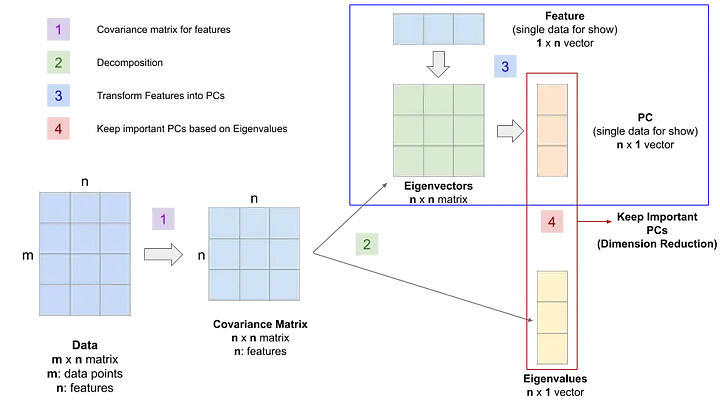

[https://towardsdatascience.com/feature-extraction-using-principal-component-analysis-a-simplified-visual-demo-e5592ced100a](https://towardsdatascience.com/feature-extraction-using-principal-component-analysis-a-simplified-visual-demo-e5592ced100a)

Principal Component Analysis (PCA) is a technique used for dimensionality reduction and data visualization by transforming the original variables into a new set of uncorrelated variables called principal components. The importance of standardization in PCA lies in ensuring that all variables contribute equally to the analysis, as PCA is sensitive to the scale of the variables.

When conducting PCA, it's common practice to standardize the features value to a zero mean and a unitary variance. Standardization helps in ensuring that all variables contribute equally to the analysis by removing differences in scale, as PCA aims to maximize variance along the directions of the principal components.

Notwithstanding z-score standardization is the most common method used in PCA, other methods of standardization can also be used. One such methods is called **Robust z-score** or **Modified z-score** and instead of using standard deviation, it uses the **Median Absolute Deviation** (MAD) [14], [15]. This method is less influenced by outliers compared to the classic one because the z-score is based on the standard deviation $\sigma$ where the distances from the mean are squared, so large deviations are weighted more heavily, and thus outliers can heavily influence it. In the modifed version, the deviations of a small number of outliers are irrelevant, making it more robust in certain situations.

% Data Standardization | PCA:
data_stand = zscore(data);
[PC_eigV, Scores, PC_var, ~, explained_var] = pca(data_stand);

% Number of PCs:
n_PCs = 3;

#### **2.2.1] Pareto Diagram and Lorenz Curve**

In multivariate statistics, Pareto diagram and Lorenz curve are both graphical methods that can be correlated to the **scree** **plot**, introduced in the 1966 by Raymond B. Cattell [16].

The **scree plot** is a downward curve that orders the eigenvalues of factors or principal components from largest to smalles. The scree plot is used to determine the suitable number of principal components to keep in PCA or FA. The procedure of finding statistically significant factors or components using a scree plot is also known as a **scree test**. According to the scree test,the "elbow" of the graph in which the eigenvalues seem to level is the point from which the components to the left should be considered significant.

It is noteworthy to precise that nowadays there are different and more appreciated techniques for the components' number selection, like the Ruscio and Roche's (2012) comparison data approach [17] that was implemented as an attempt to overcome the subjective weakness of Cattell's scree test. 

The Pareto diagram is a monotonically decreasing bar plot that follows the scree plot profile, while the Lorenz curve has an increasing monotonicity since it is based on the cumulative sum of the variances explained by each principal component.

In the *x axis* we have the Principal Components (PCs). 

In the *y axis *we have the 'Variance Accounted For' (VAF) which is a measure used in PCA to assess the proportion of total variance in the data that is explained by each principal component. For each principal component, the VAF indicates the percentage of variance in the original dataset that is captured by that component. It helps in understanding how much information is retained when reducing the dimensionality of the data using PCA.

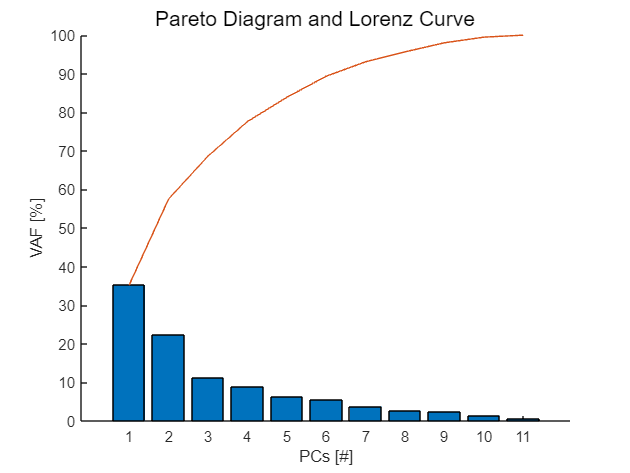

figure('Name', 'Pareto-Lorenz');
hold on

% Plot of the fraction of variance explained by each PC.
% bar(100.* PC_var./ sum(PC_var)) = bar(explained_var)
bar(explained_var)

% Set x-axis ticks to have all PC values
xticks(1 : numel(PC_var))

% Plot of the cumulative fraction of variance
line(1 : numel(PC_var), 100.* cumsum(PC_var)./ sum(PC_var))

sgtitle('Pareto Diagram and Lorenz Curve')
xlabel('PCs [#]') 
ylabel('VAF [%]') 
ylim([0 100])
box off

#### **2.2.2] PCA Biplot  [Multi-Class]**

All 11 features are represented in this biplot by vectors, and the direction and length of the vectors indicate how each variable contributes to the *n_PCs = 3* principal components in the plot. 

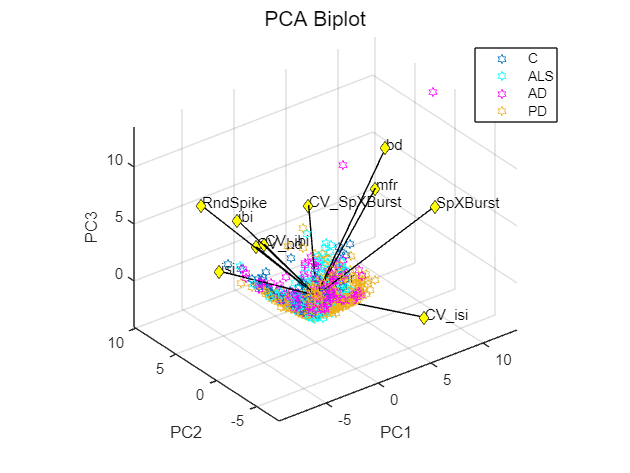

figure ('Name', 'Biplot');
hold on

% Project the original data matrix into the reduced space defined by the first 3 eigenvectors of . 
scatter3(Scores(is_0, 1), Scores(is_0, 2), Scores(is_0, 3), 'hexagram', 'MarkerEdgeColor', [0 0.4470 0.7410]);
scatter3(Scores(is_1,  1), Scores(is_1, 2), Scores(is_1, 3), 'hexagram', 'MarkerEdgeColor', [0 1 1]);
scatter3(Scores(is_2, 1), Scores(is_2, 2), Scores(is_2, 3), 'hexagram', 'MarkerEdgeColor', [1 0 1]);
scatter3(Scores(is_3, 1), Scores(is_3, 2), Scores(is_3, 3), 'hexagram', 'MarkerEdgeColor', [0.9290 0.6940 0.1250]);

xlabel('PC1')
ylabel('PC2')
zlabel('PC3')
sgtitle('PCA Biplot')

% Scale factor
scale_f = 20;

% Scaled eigenvectors biplot
biplot(scale_f * PC_eigV(:, 1:n_PCs), 'Color', 'k', 'Marker', 'diamond', 'MarkerFaceColor', 'y', "VarLabels", features);

box off
grid on
legend(real_class_labels)
hold off
axis equal
view(3)

#### **2.2.3] PCA Biplot  [Binary] | Features Selection**

This section will be reserved for a binary comparison of PCA between all possible pairwise combinations among the four classes.

The code will be similar to the one presented in in Section 4 but here the aim is to compare the PCA biplots of the 3 features that captures the most variance of the first n_PCs = 3 principal components. 

Section 4 is focused on the feature selection based on Fisher LDA classification algorithm.

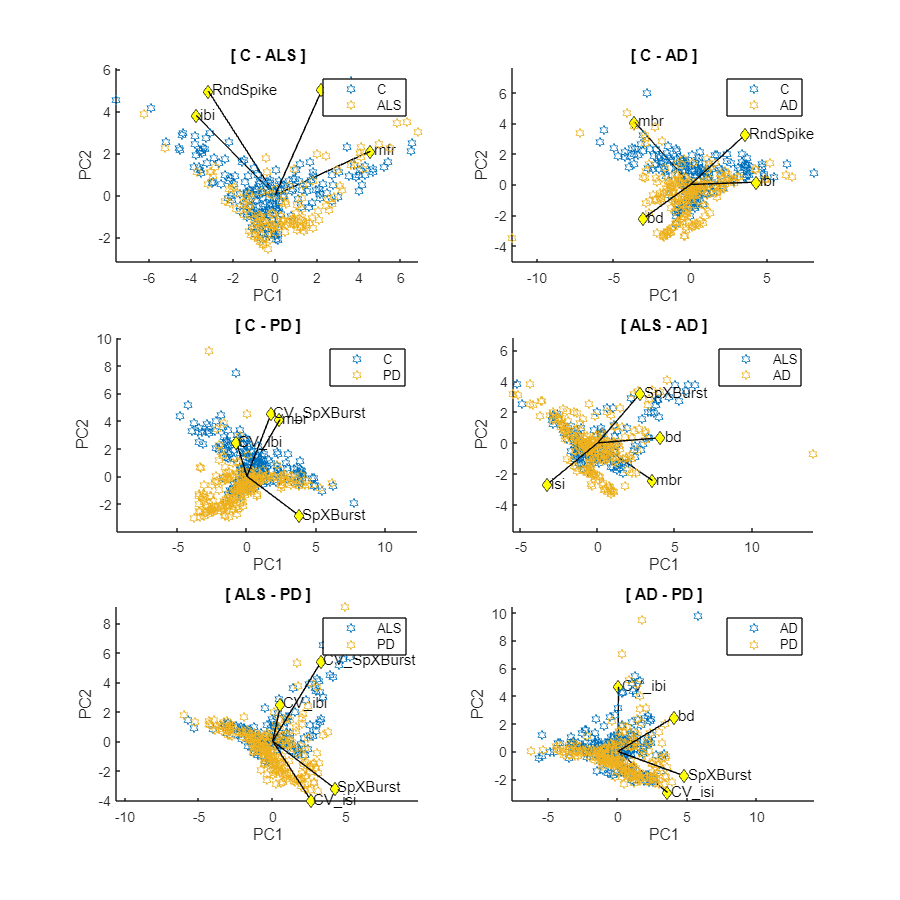

f_bin_PCA = figure('Name', 'PCA Binary', 'Position', [50, 50, 2000, 2000]);

% Combinations of pairwise binary comparison:
n_comb_PCA = numel(class_labels) * ((numel(class_labels) - 1) / 2);

% Initialization:
PCA_binary_feat = cell(n_comb_PCA, 1);
binary_feat = cell(n_PCs, 1);

% N° of features to consider for each classification:
n_feat_PCA = 4;

% Counter:
counter_PCA = 1;

% Since the classes are just int from 0 to 3 it is easy to use nested for
% loops to implement pairwise comparison:
for i = 0 : numel(class_labels)

    for j = i+1 : (numel(class_labels)-1)

        % Filter dataset for the current pair of classes:
        subset_data_PCA = data_stand(ismember(classes, [i, j]), :);
        subset_class_labels_PCA = classes(ismember(classes, [i, j]));
        
        % Classes indexes:
        is_i = find(subset_class_labels_PCA == i);
        is_j = find(subset_class_labels_PCA == j);

        [coeff, scores, latent] = pca(subset_data_PCA, 'NumComponents', n_PCs);

        % Calculate the mean or absolute mean of weights across the firsT 3 PCs:
        % This can be avoided by considering just the first PC, 
        % but it would not capture a more precise estimation of the dataset variability
        mean_weights = mean(abs(coeff), 2);
        
        % Identify the features with the highest absolute mean weights:
        [sorted_weights, sorted_idx] = sort(mean_weights, 'descend');
        
        % Features selection:
        top_idx = sorted_idx(1 : n_feat_PCA); 
        top_features = features(top_idx);

        % Save important features for each binary classification:
        PCA_binary_feat{counter_PCA} = top_features;

        % Graphical aspects:
        figure(f_bin_PCA)
        subplot(n_comb_PCA/(n_comb_PCA/3), n_comb_PCA/(n_comb_PCA/2), counter_PCA)
        hold on

        scatter(scores(is_i, 1), scores(is_i, 2), 'hexagram', 'MarkerEdgeColor', [0 0.4470 0.7410]);
        scatter(scores(is_j, 1), scores(is_j, 2), 'hexagram', 'MarkerEdgeColor', [0.9290 0.6940 0.1250]);

        biplot(10 * coeff(top_idx, 1:n_PCs), 'Color', 'k', 'Marker', 'diamond', 'MarkerFaceColor', 'y', "VarLabels", top_features);

        title_str = sprintf('[ %s - %s ]', real_class_labels{i+1}, real_class_labels{j+1});
        title(title_str);
        legend(real_class_labels{i+1}, real_class_labels{j+1})
        xlabel('PC1')
        ylabel('PC2')
        box off
        hold off
        axis equal
        view(2)
        
        % Counter increasing:
        counter_PCA = counter_PCA + 1;
    end
end

### 2.3] Data Partitioning

Data partitioning involves dividing the dataset into subsets: training set, test set and validation set:

- *training* set is used to train the model;

- *test* set is used to evaluate its performance, if the data in the test set has never been used in training it is also called a **holdout data set;**

- *validation* set can be used for **regularization** by **early stopping **(stopping training when the error on the validation data set increases, as this is a sign of **overfitting** to the training data set.

For this project, the dataset is partitioned using a holdout method, creating two main subsets for training and testing. The Stratification option is employed to ensure that the proportion of classes in the original dataset is maintained in both subsets.

The code allows for the selection of the dataset on which to apply the classification algorithm. Although the conventional approach is to classify the original dataset, recent experiments have indicated enhanced classifier performance when trained on the PCA scores, both in terms of accuracy and AUC [18], [19]. Consequently, the classification can be conducted on the original dataset (rigorous option) or on the principal components scores.

% Classification dataset choice: 
% - PCA Scores
% - Original dataset
choice_data = data

choice_data = 1.0e+03 *

    0.0019    0.0247    0.0067    0.0129    0.0005    0.1444    0.0006    0.0069    0.0020    0.4616    0.0075
    0.0010    0.0458    0.0043    0.0078    0.0003    0.1235    0.0006    0.0081    0.0017    0.8516    0.0055
    0.0020    0.0088    0.0049    0.0227    0.0005    0.1766    0.0004    0.0108    0.0016    0.4400    0.0052
    0.0069    0.0112    0.0142    0.0261    0.0009    0.2159    0.0008    0.0039    0.0026    0.1439    0.0066
    0.0018    0.0146    0.0064    0.0147    0.0004    0.1524    0.0005    0.0082    0.0018    0.4810    0.0066
    0.0017    0.0259    0.0063    0.0119    0.0005    0.1709    0.0007    0.0083    0.0019    0.5620    0.0043
    0.0043    0.0190    0.0122    0.0172    0.0007    0.1463    0.0008    0.0042    0.0024    0.2316    0.0076
    0.0024    0.0123    0.0061    0.0203    0.0004    0.2392    0.0006    0.0094    0.0018    0.4235    0.0059
    0.0048    0.0116    0.0093    0.0276    0.0010    0.2738    0.0037    0.0054    0.0

% Create a holdout partition (60 % training, 40 % test).
% 'Stratify' = true ensure that both training and test sets mantain the same
% classes proportion as the original dataset.
cvp = cvpartition(classes, 'HoldOut', 0.4, 'Stratify', true);

% Obtain the actual training and test sets:
test_idx = cvp.test;
train_idx = cvp.training;

% Data:
test = choice_data(test_idx, :);
train = choice_data(train_idx, :);

% Labels:
test_w = classes(test_idx);
train_w = classes(train_idx);

## 3] CLASSIFICATION  [Multi-Class]

This project revolves around a dataset of four distinct classes [Section 2], so the classification algorithm should be based on a multi-class perspective. 

The existing multi-class classification techniques can be categorised into :

- *transformation to binary* 

- *extension from binary*

- *hierarchical classification.*

Generally, the commonly used methodologies revolve around the first two categories. 

1] *Transformation to binary* opts for dividing the multi-class classification problem into multiple binary problems, employing **binarization** techniques [20].

Notably, binarization algorithms are further delineated into two main paradigms: 

- the **one-versus-one** (**OvO**) approach [21], which consists in dividing the problem into as many binary problems as all the possible combinations between pairs of classes :


$$n_{classification} = \frac{n_{classes} \cdot (n_{classes} - 1)}{2}$$
 

            Each classifier in the OVO discriminates between a pair of classes {$c_i$, $c_j$} so one classifier is learned to discriminate between each pair, and then the outputs of these base         classifiers are combined in order to predict the output class (Perceptrons are examples of OvO);

- the **one-versus-all** (**OvA**) or **one-versus-rest** (**OvR**) approach, which learns a classifier for each class, where the class is distinguished from all other classes, so the base classifier giving a positive answer indicates the output class (Multinomial Logistic Regression is an example of OvR).

While OvO generates a score matrix from all binary classifiers, its limitation lies in potential invalid discrimination when the true label does not belong to both classes in a classifier. On the other hand, OvA, with fewer resources, treats one class as positive and the rest as negative, offering a practical alternative, especially with an expanding dataset. 

2] *Extension from binary* involves expanding binary classifiers into multiclass. Several algorithms have been developed based on Neural Networks, Decision Trees, Naïve Bayes and Support Vector Machines [22]. These types of techniques can also be called algorithm adaptation techniques.

In order to have a wide perspective on this type of algorithm we have decided to implement both the transformation and the extension techniques we opted for Naïve Bayes, Multinomial Logistic Regression, LDA, Decision Tree and SVM.

For each type of classifier:

- Training set for model parameters estimation.

- Classifier predictions for both training and test sets.

For all classifier: 

- Confusion Matrices

- Accuracy

- ROC Curves

The ROC curve provides a graphical representation of the classifier's ability to discriminate between classes by plotting the true positive rate (*SENSITIVITY*) against the false positive rate (*1 - SPECIFICITY*) at various threshold settings. It helps assess the trade-off between sensitivity and specificity and provides insights into the classifier's performance across different threshold values.

The confusion matrix is a tabular representation that summarizes the performance of a classifier by comparing predicted labels against true labels. It provides information about true positives, true negatives, false positives, and false negatives, allowing for a more detailed understanding of the classifier's strengths and weaknesses. From the confusion matrix, various performance metrics such as accuracy, precision, recall, and F1-score can be calculated, providing a comprehensive assessment of classifier performance across different classes.

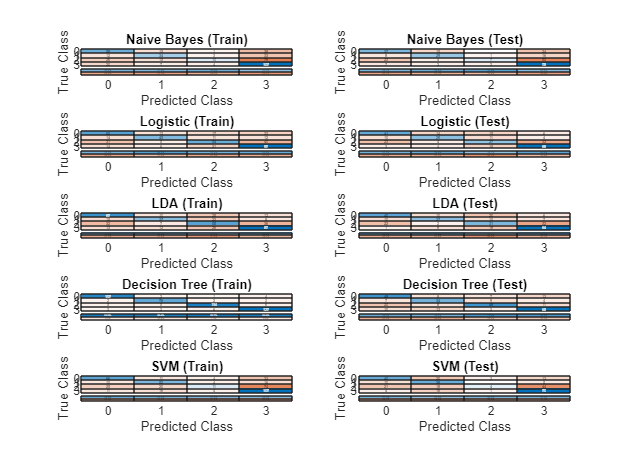

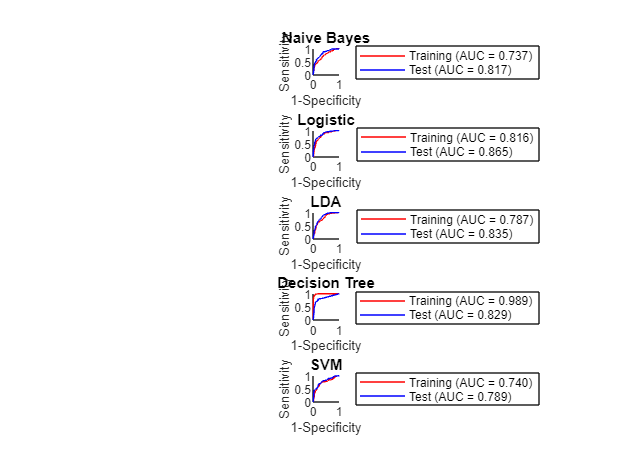

classif_list = ["Naive Bayes", "Logistic", "LDA", "Decision Tree", "SVM"];

% for all confusion matrices
f1 = figure('Name', 'Confusion Chart');
 
% for all ROC curves
f2 = figure('Name', 'ROC Curves');

for cl = 1 : length(classif_list)

    classif = classif_list(cl);

    switch (classif)

#### 3.1] Naïve Bayes

The `*fitcnb*` function in MATLAB is used for training a Naïve Bayes classifier. Naïve Bayes is a type of probabilistic classifier based on Bayes' theorem with the "naive" assumption of independence between features. 

This function is very useful because it can handle missing data effectively. They can compute class probabilities even when some features are missing, making them robust in real-world scenarios where data may be incomplete or noisy.  Once trained, the `*fitcnb*` function returns the trained classifier model, which can then be used to classify new data points.

Naïve Bayes is a successful classifier based upon the principle of maximum a posteriori (MAP). This approach is naturally extensible to the case of having more than two classes, and was shown to perform well in spite of the underlying simplifying assumption of conditional independence.

        case "Naive Bayes"

            NBmodel = fitcnb(train, train_w);
            
            % Predictions on the test set
            [label_te, Posterior_te] = predict(NBmodel, test);

            % Prediction for the training set
            [label_tr, Posterior_tr] = predict(NBmodel, train);

#### 3.2] Multinomial Logistic Regression

In multinomial logistic regression or 'softmax regression' there is no need for the independent variables to be statistically independent from each other (unlike in a the Naïve Bayes).

The ‘[*fitmnr*](https://it.mathworks.com/help/stats/fitmnr.html)*’* function can handle multi-class classification appliyng a OvA as default method.

As in the previous case, the function can handle response variables with more than two classes. It uses a set of dummy variables to represent the different classes, and the multinomial logistic regression model estimates separate coefficients for each class. After fitting the model, it returns the estimated coefficients, which can be used to make predictions on new data. 

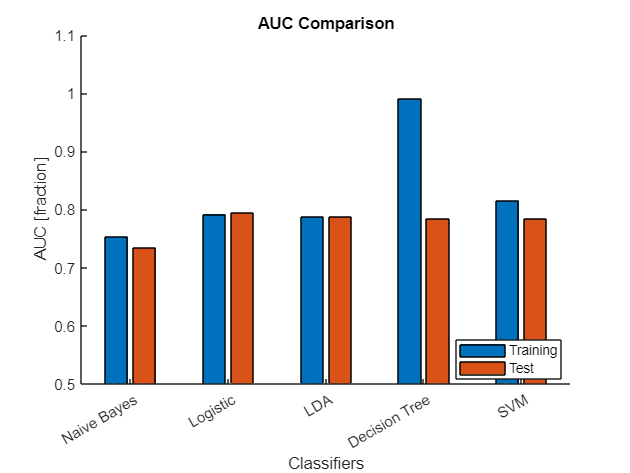

        case "Logistic"

            LRmodel = fitmnr(train, train_w);


            % Predictions on the test set
            [label_te, Posterior_te] = predict(LRmodel, test);

            % Prediction for the training set
            [label_tr, Posterior_tr] = predict(LRmodel, train);

The best classifier for the TEST set based on AUC results is: Logistic [AUC = 0.794]

#### 3.3] LDA  

For this classifier we implemented a function [LDA_multiclass] based on Fisher Linear Discriminant Analysis for the multi-class case. We have consulted several sources and also the 2 PDFs :

- *'*[*ABDS_C2_classifiers*](https://2023.aulaweb.unige.it/pluginfile.php/292740/mod_resource/content/0/ABDS_C2_classifiers.pdf)*'  *by Professor V. Sanguineti (University of Genoa).

- *'*[*A Tutorial on Data Reduction*](https://sci.utah.edu/~shireen/pdfs/tutorials/Elhabian_PCA09.pdf)*'  *by Professor Aly A. Farag (University of Louisville).

The LDA model can be fitted using *`*[*fitcdiscr*](https://it.mathworks.com/help/stats/fitcdiscr.html#bt6d86x-5)*`.*

        case "LDA" 

The most accurate classifier for the TEST set is: Decision Tree [Accuracy = 63.312]


            % W matrix from LDA multiclass
            W = LDA_multiclass(train, train_w);

            % Projection of both test and train data on W 
            Ztr = train * W;
            Zte = test * W;

            % Fit LDA model on the projected data
            LDAmodel = fitcdiscr(Ztr, train_w);

            % Predictions on the test set
            [label_te, Posterior_te] = predict(LDAmodel, Zte);
 
            % Predictions on the train set
            [label_tr, Posterior_tr] = predict(LDAmodel, Ztr);

#### 3.4] Decision tree

[Decision tree](https://en.wikipedia.org/wiki/Decision_tree_learning) learining is a method used in data analysis and machine learning. It involves creating a tree-like structure where each node represents a decision based on a feature, leading to outcomes represented by leaf nodes. Decision trees are used for classification and regression tasks and offer interpretability, feature selection, and anomaly detection capabilities.

To fit the model '[*fitctree*](https://it.mathworks.com/help/stats/fitctree.html)'.

        case "Decision Tree"


fig_LDA =   Figure (13: LDA Features) with properties:

      Number: 13
        Name: 'LDA Features'
       Color: [0.9400 0.9400 0.9400]
    Position: [50 50 2000 2000]
       Units: 'pixels'

  Show all properties


            TREEmodel = fitctree(train, train_w);

            % Prediction on the test set
            [label_te, Posterior_te] = predict(TREEmodel, test);

            % Prediction on the train set
            [label_tr, Posterior_tr] = predict(TREEmodel, train);

#### 3.5] SVM

[Support vector machines](https://en.wikipedia.org/wiki/Support_vector_machines) are based upon the idea of maximizing the margin between classes, i.e. maximizing the minimum distance from the separating hyperplane to the nearest example. The basic SVM supports only binary classification, but extensions have been proposed to handle the multiclass classification case as well. In these extensions, additional parameters and constraints are added to the optimization problem to handle the separation of the different classes.

The SVM is one of the most famous and utilized supervised learning method [23] and can be implemented in Matlab using `[*fitcecoc*](https://it.mathworks.com/help/stats/fitcecoc.html)`.

The function `[*fitcecoc*](https://it.mathworks.com/help/stats/fitcecoc.html)` trains a multiclass, error-correcting output codes (ECOC) model using  $\frac{K(K-1)}{2}$ binary models, with K representing the number of unique class labels. The coding design used is OvO.

        case "SVM"

            SVMmodel = fitcecoc(train, train_w);
            
            % Predictions on the test set
            [label_te, Posterior_te] = predict(SVMmodel, test);

            % Predictions on the test set
            [label_tr, Posterior_tr] = predict(SVMmodel, train);

        otherwise
            error('Unknown classifier type.');
    end 

**Accuracy**


$$Accuracy$$
 
$$=$$
 
$$\frac{(TP + TN)}{(TP + TN + FP + FN)}$$


Accuracy is computed as the sum of the correct classification, e.g. the diagonal elements of the confusion matrix divided by all the sum of all elements, to obtain the percentage, just multiply by 100.

    % Compute accuracy for training and test sets
    % Calculate confusion matrix for training and test sets
    confusion_tr = confusionmat(train_w, label_tr);
    confusion_te = confusionmat(test_w, label_te);

    % Calculate accuracy for training and test sets
    accuracy_tr = (sum(diag(confusion_tr)) / sum(confusion_tr(:))) * 100;
    accuracy_te = (sum(diag(confusion_te)) / sum(confusion_te(:))) * 100;
    allACCU(cl,:) = [accuracy_tr accuracy_te];

**Confusion Chart**

In addition to the confusion chart, we decided to display the column-normalized summary, that is the number of correctly and incorrectly classified observations for each predicted class as percentages of the number of observations of the corresponding predicted class. The percentages of correctly classified observations can be thought of as class-wise precisions (or positive predictive values).

    figure(f1)

    subplot(length(classif_list), 2, 2*cl-1)
    confusionchart(train_w, label_tr, 'ColumnSummary','column-normalized')
    title(sprintf('%s (Train)', classif_list(cl)));

    subplot(length(classif_list), 2, 2*cl)
    confusionchart(test_w, label_te, 'ColumnSummary','column-normalized')
    title(sprintf('%s (Test)', classif_list(cl)));

**ROC Curve**

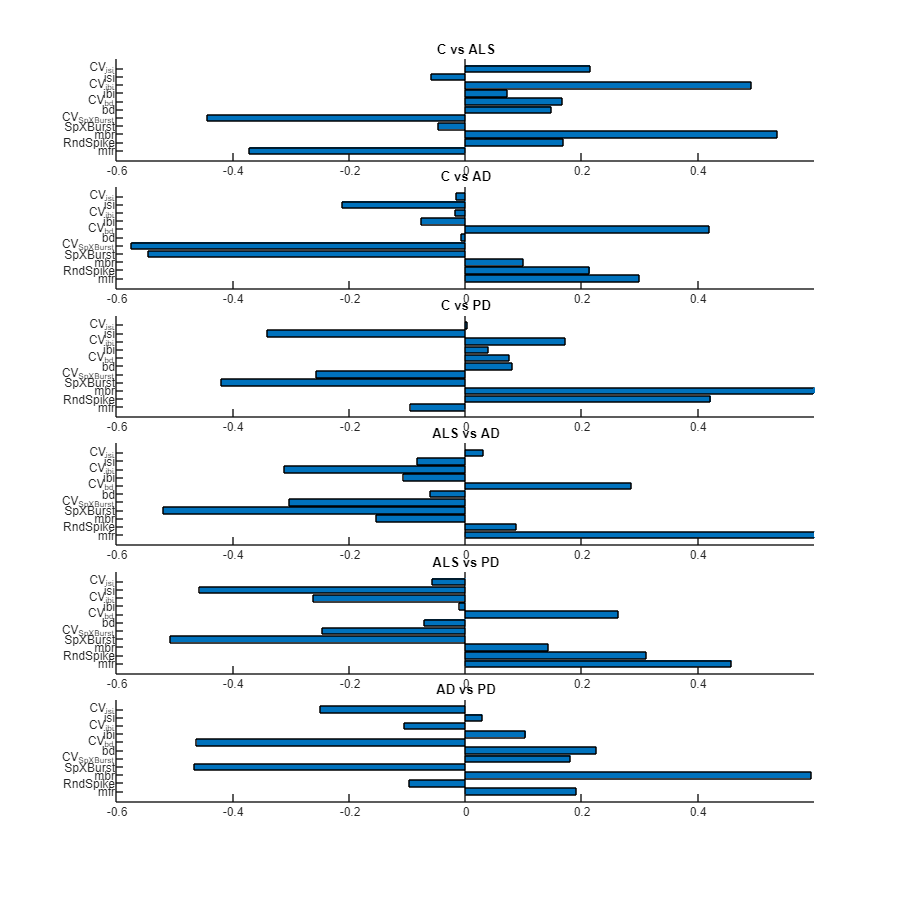

Best features for binary classification between C and ALS are:
1] mbr: w = 0.537
2] CV_ibi: w = 0.492
3] CV_SpXBurst: w = -0.445

Best features for binary classification between C and AD are:
1] CV_SpXBurst: w = -0.575
2] SpXBurst: w = -0.546
3] CV_bd: w = 0.419

Best features for binary classification between C and PD are:
1] mbr: w = 0.642
2] RndSpike: w = 0.422
3] SpXBurst: w = -0.420

Best features for binary classification between ALS and AD are:
1] mfr: w = 0.636
2] SpXBurst: w = -0.521
3] CV_ibi: w = -0.312

Best features for binary classification between ALS and PD are:
1] SpXBurst: w = -0.508
2] mfr: w = 0.457
3] isi: w = -0.457

Best features for binary classification between AD and PD are:
1] mbr: w = 0.595
2] SpXBurst: w = -0.467
3] CV_bd: w = -0.463



    figure(f2)

    subplot(length(classif_list), 1, cl)
     
    % Choice of class 3 [AD] as positive class and the posterior scores must
    % correnspond to this positive class.
    [xtr, ytr, ~, AUCtr] = perfcurve(train_w, Posterior_tr(:, 4), 3);
    [xte, yte, ~, AUCte] = perfcurve(test_w, Posterior_te(:, 4), 3);


    plot(xtr, ytr,'r')
    hold on
    plot(xte, yte,'b')

    xlabel('1-Specificity')
    ylabel('Sensitivity')

    title(classif_list(cl), 'FontSize', 10)
    legend_tr = sprintf('Training (AUC = %.3f)', AUCtr);
    legend_test = sprintf('Test (AUC = %.3f)', AUCte);
    legend({legend_tr, legend_test}, 'FontSize', 8, 'Location', 'best');
   
    axis square
    box off
    allAUC(cl,:) = [AUCtr AUCte];
   
end

**AUC Comparison**

figure('Name', 'AUC Comparison')
bar(allAUC)

% Adjust axis to display a better comparison and labels
ylim([0.5 1.1])
xticklabels(classif_list)
xticks(1 : length(classif_list))
xlim([0.5 length(classif_list) + 0.5])
box off

legend('Training', 'Test', 'Location', 'best')
title('AUC Comparison')
xlabel('Classifiers')
ylabel('AUC [fraction]')

[m_AUC, i] = max(allAUC(:, 2));
[m_Accu, j] = max(allACCU(:, 2));

fprintf('The best classifier for the TEST set based on AUC results is: %s [AUC = %.3f]', classif_list{i}, m_AUC);
fprintf('The most accurate classifier for the TEST set is: %s [Accuracy = %.3f]', classif_list{j}, m_Accu);

## 4] LDA [Binary] | Features selection

In this section a binary classifier based on Linear Discriminant Analysis implemented in the *'Lab Activity 4*' is used in order to evaluate the most important features that may be considered to obtain a binary distinction.

Specifically, an One-vs-One (OvO) approach will be employed, considering all possible pairwise combinations among the four classes. This strategy aims to determine the most effective features for accurately classifying and distinguishing each case.

**N.B**: As shown during lectures the data standardization is a fundamental step to have equal variance features.

% N° of features to consider for each classification:
n_feat_LDA = 3;

% Applying the OvO number of combinations:
n_comb_LDA = n_comb_PCA;

% Initialization:
W_LDA = cell(n_comb_LDA, 1);
LDA_binary_feat = cell(n_comb_LDA, 1);
feat = cell(n_feat_LDA, 1);

counter_LDA = 1;
fig_LDA = figure('Name', 'LDA Features', 'Position', [50, 50, 2000, 2000])

% Nested loops for pairwise comparisons:
for i = 0 : numel(class_labels)

    for j = i+1 : (numel(class_labels)-1)

        % Filter dataset for the current pair of classes
        subset_data_LDA = data_stand(ismember(classes, [i, j]), :);
        subset_class_labels_LDA = classes(ismember(classes, [i, j]));

        W_LDA{counter_LDA} = ldaclass_one(subset_data_LDA, subset_class_labels_LDA, [i, j]);

        % Most relevant features for binary classification.
        % Find the n° features indices that correnspond to the maximum weight:
        [~, idx] = maxk(abs(W_LDA{counter_LDA}), n_feat_LDA);

        % for-loop just to create the string for each matrix inside cells:
        for k = 1 : n_feat_LDA
            feat{k} = sprintf('%.0f] %s: w = %.3f', k, features{idx(k)}, W_LDA{counter_LDA}(idx(k)));
        end
        
        % Display information for each comparison
        fprintf('Best features for binary classification between %s and %s are:\n%s\n\n', ...
            real_class_labels{i+1}, real_class_labels{j+1}, strjoin(feat, '\n'));

        % Save important features for each binary classification:
        LDA_binary_feat{counter_LDA} = feat;

        figure(fig_LDA)

        % Graphical aspects:
        subplotPos = get(subplot(n_comb_LDA, 1, counter_LDA), 'Position');
        % Set subplots high:
        subplotPos(4) = subplotPos(4) * 1.1; 
        set(subplot(n_comb_LDA, 1, counter_LDA), 'Position', subplotPos);

        barh(W_LDA{counter_LDA})
        yticklabels(features);
        xlim([-0.6 0.6]);
        title_str = sprintf('%s vs %s', real_class_labels{i+1}, real_class_labels{j+1});
        title(title_str);
        box off
        
        counter_LDA = counter_LDA + 1;
    end
end

## 5] DISCUSSION

In addition to the results presented in the live-script, certain considerations merit attention at this stage. 

The project served as an exploratory attempt to assess various classification algorithms. The empirical evidence supports the Decision Tree classifier as the most effective for the training set. However, the performance on the test set exhibits variability contingent on the designation of the 'positive class' and the proportion of the 'holdout' partition, aligning with established literature acknowledging such variability.

Significant findings include improved classification performance following outlier replacement in Section 2 and the decision to fit classifiers on PCA scores rather than the original dataset. Notably, this approach is acknowledged as random, as highlighted in Section 3, given the prevalent preference in scientific research for classification on the original dataset.

It is crucial to note that overall classifier performances are suboptimal due to the dataset's concentration and the absence of distinct demarcation between populations, that would have also disadvantaged other types of techniques like unsupervised learning approaches (e.g. clustering).

For future work, enhancing classification efficiency through the application of cross-validation techniques is essential. Additionally, incorporating a validation set is recommended to mitigate the risk of overfitting. These methodological adjustments are crucial for advancing the reliability and generalizability of the classification framework.

## 6] Bibliography

- [1]  Prince M., Wimo A., Guerchet M., Ali G-C., Yu-Tzu W., Prina M.: '[World Alzheimer Report 2015, The Global Impact of Dementia: an analysis of prevalence, incidence, cost and trends](https://www.alzint.org/about/dementia-facts-figures/dementia-statistics/)'. *Alzheimer’s Disease International (ADI)*; (2015). Available from: [https://www.alz.co.uk/research/WorldAlzheimerReport2015.pdf](https://www.alz.co.uk/research/WorldAlzheimerReport2015.pdf) 

- [2] A.Tăuţan, B. Ionescu, E. Santarnecchi: ['Artificial intelligence in neurodegenerative diseases: A review of available tools with a focus on machine learning techniques](https://www.sciencedirect.com/science/article/abs/pii/S0933365721000749)', *Artificial Intelligence in Medicine, *vol. 117, art. 102081; (2021), doi: [https://doi.org/10.1016/j.artmed.2021.102081](https://doi.org/10.1016/j.artmed.2021.102081) .

- [3] M. Belić, V. Bobić, M. Badža, N. Šolaja, M. Đurić-Jovičić, V.S. Kostić: '[Artificial intelligence for assisting diagnostics and assessment of Parkinson's disease—a review](https://www.sciencedirect.com/science/article/abs/pii/S0303846719302380?via%3Dihub)', *Clinical Neurology and Neurosurgery, *vol. 184, art. 105442; (2019), doi: [https://doi.org/10.1016/j.clineuro.2019.105442](https://doi.org/10.1016/j.clineuro.2019.105442) .

- [4] Saboo K.V., Hu C., Varatharajah Y., Przybelski S.A., Reid R.I., Schwarz C.G., Graff-Radford J., Knopman D.S., Machulda M.M., Mielke M.M., Petersen R.C., Arnold P.M., Worrell G.A., Jones D.T., Jack C.R., Jr, Iyer R.K., Vemuri P.: '[Deep learning identifies brain structures that predict cognition and explain heterogeneity in cognitive aging](https://www.ncbi.nlm.nih.gov/pmc/articles/PMC9045384/)', *NeuroImage, *vol. 251, art. 119020; (2022), doi: [https://doi.org/10.1016/j.neuroimage.2022.119020](https://doi.org/10.1016/j.neuroimage.2022.119020) .

- [5] Suk H.I., Shen D. : '[Deep learning-based feature representation for AD/MCI classification](https://www.ncbi.nlm.nih.gov/pmc/articles/PMC4029347/)', *Med Image Comput Comput Assist Interv., *vol. 16(2), pp. 583–590; (2013), doi: [https://doi.org/10.1007/978-3-642-40763-5_72](https://doi.org/10.1007/978-3-642-40763-5_72) .

- [6] Thomson J.A., Itskovitz-Eldor J., Shapiro S.S., Waknitz M.A., Swiergiel J.J., Marshall V.S., Jones J.M., '[Embryonic stem cell lines derived from human blastocysts](https://pubmed.ncbi.nlm.nih.gov/9804556/)', *Science*, vol 282(5391), pp. 1145-7; (1998), doi: [10.1126/science.282.5391.1145](https://doi.org/10.1126/science.282.5391.1145) .

- [7] Takahashi K., Tanabe K., Ohnuki M., Narita M., Ichisaka T., Tomoda K., Yamanaka S., '[Induction of pluripotent stem cells from adult human fibroblasts by defined factors](https://pubmed.ncbi.nlm.nih.gov/18035408/)', *Cell*., vol. 131(5), pp. 861-872. (2007), doi: [https://doi.org/10.1016/j.cell.2007.11.019](https://doi.org/10.1016/j.cell.2007.11.019) .

- [8] Cho, G., Yim, J., Choi, Y., Ko, J., & Lee, S. H. : '[Review of Machine Learning Algorithms for Diagnosing Mental Illness](https://www.ncbi.nlm.nih.gov/pmc/articles/PMC6504772/)', *Psychiatry investigation*, vol. *16*(4), pp. 262–269. (2019), doi: [https://doi.org/10.30773/pi.2018.12.21.2](https://doi.org/10.30773/pi.2018.12.21.2) .

- [9] B. Mossink, A.H.A. Verboven, E.J.H. van Hugte, T.M. Klein Gunnewiek, G. Parodi, K. Linda, C. Schoenmaker, T. Kleefstra, T. Kozicz, H. van Bokhoven, D. Schubert, N. Nadif Kasri, M. Frega : '[Human neuronal networks on micro-electrode arrays are a highly robust tool to study disease-specific genotype-phenotype correlations in vitro](https://www.cell.com/stem-cell-reports/fulltext/S2213-6711(21)00326-X?_returnURL=https%3A%2F%2Flinkinghub.elsevier.com%2Fretrieve%2Fpii%2FS221367112100326X%3Fshowall%3Dtrue)', *bioRxiv, * vol. 16(9), pp. 2182-2196. (2021), doi: [https://doi.org/10.1101/2021.01.20.427439](https://doi.org/10.1101/2021.01.20.427439) .

- [10] Frega, M., Linda, K., Keller, J.M. *et al.* : '[Neuronal network dysfunction in a model for Kleefstra syndrome mediated by enhanced NMDAR signaling](https://www.nature.com/articles/s41467-019-12947-3)', *Nat Commun, *vol. 10, art. 4928. (2019), doi: [https://doi.org/10.1038/s41467-019-12947-3](https://doi.org/10.1038/s41467-019-12947-3) .

- [11] A. M. Tukker, Fiona M.J. Wijnolts, Aart de Groot, Remco H.S. Westerink: '[Human iPSC-derived neuronal models for in vitro neurotoxicity assessment](https://www.sciencedirect.com/science/article/pii/S0161813X18302122)', *Neurotoxicology,* vol. 67, pp. 215-225. (2018), doi: [https://doi.org/10.1016/j.neuro.2018.06.007](https://doi.org/10.1016/j.neuro.2018.06.007) .

- [12]  S. Serneels, T. Verdonck: '[Principal component analysis for data containing outliers and missing elements](https://www.sciencedirect.com/science/article/pii/S0167947307002241)', *Computational Statistics & Data Analysis, *vol. 52, no. 3; (2008), pp. 1712-1727, doi: [https://doi.org/10.1016/j.csda.2007.05.024](https://doi.org/10.1016/j.csda.2007.05.024) .

- [13] Mia Hubert, P. Rousseeuw, T. Verdonck: '[Robust PCA for skewed data and its outlier map](https://www.sciencedirect.com/science/article/pii/S0167947308002879)',  *Computational Statistics & Data Analysis, *vol. 53, no. 6; (2009), pp. 2264-2274, doi: [https://doi.org/10.1016/j.csda.2008.05.027](https://doi.org/10.1016/j.csda.2008.05.027) .

- [14]  [Modified z score - IBM Documentation](https://www.ibm.com/docs/en/cognos-analytics/11.1.0?topic=terms-modified-z-score) . 

- [15]  [Outliers make us go MAD: Univariate Outlier Detection | by João Rodrigues | Medium](https://medium.com/@joaopedroferrazrodrigues/outliers-make-us-go-mad-univariate-outlier-detection-b3a72f1ea8c7) . 

- [16] Cattell R.B. : '[The Scree Test For The Number Of Factors](https://pubmed.ncbi.nlm.nih.gov/26828106/)', *Multivariate Behav Res*., 1(2) pp. 245-76, (1966) doi: [10.1207/s15327906mbr0102_10](https://doi.org/10.1207/s15327906mbr0102_10) .

- [17] Ruscio J, Roche B. : '[Determining the number of factors to retain in an exploratory factor analysis using comparison data of known factorial structure](https://pubmed.ncbi.nlm.nih.gov/21966933/)', *Psychol Assess, *vol. 24(2), pp. 282-92. (2012) doi: [https://doi.org/10.1037/a0025697](https://psycnet.apa.org/doi/10.1037/a0025697) 

- [18] Omuya E.O., Okeyo G.O., Kimwele M.W. : '[Feature selection for classification using principal component analysis and information gain](https://www.sciencedirect.com/science/article/abs/pii/S0957417421002062)',* Expert Systems with Applications*, vol. 174, art. 114765. (2021), doi: [https://doi.org/10.1016/j.eswa.2021.114765](https://doi.org/10.1016/j.eswa.2021.114765) .

- [19] Rozenn Dahyot : '[Principal Component Classification](https://arxiv.org/pdf/2210.12746.pdf)' [PDF],  [arXiv:2210.12746](https://arxiv.org/abs/2210.12746) [cs.LG].

- [20] M. Galar, A. Fernández, E. Barrenechea, H. Bustince and F. Herrera: ** '**[An Overview of Ensemble Methods for Binary Classifiers in Multi-class Problems: Experimental Study on One-vs-One and One-vs-All Schemes](https://sci2s.ugr.es/ovo-ova#One-vs-One%20decomposition%20scheme)',* Pattern Recognition, *vol. 44(8), pp.1761-1776. (2011), doi: [10.1016/j.patcog.2011.01.017](http://dx.doi.org/10.1016/j.patcog.2011.01.017).

- [21] Liu Y., Bi J.-W., Fan Z.-P. : '[A method for multi-class sentiment classification based on an improved one-vs-one (OVO) strategy and the support vector machine (SVM) algorithm](https://www.sciencedirect.com/science/article/pii/S002002551631043X)', *Inform. Sci*., 394–395, pp. 38-52 (2017), doi: [10.1016/j.ins.2017.02.016](https://doi.org/10.1016/j.ins.2017.02.016) .

- [22] De Lima M.D., Costa N.L., Barbosa R. : '[Improvements on least squares twin multi-class classification support vector machine](https://www.sciencedirect.com/science/article/pii/S0925231218307768)', *Neurocomputing*, vol. 313, pp. 196-205. (2018), doi: [10.1016/j.neucom.2018.06.040](https://doi.org/10.1016/j.neucom.2018.06.040) .

- [23] Hearst M.A., Dumais S.T., Osuna E., Platt J., Scholkopf B.. : '[Support vector machines](https://ieeexplore.ieee.org/abstract/document/708428?casa_token=OrGwbxW2aFoAAAAA:j1LXwNTv53MnQm2z8zjwpA9b_hNqm_GSKBW5pMivpR2Uab5XBi5P0woAVTXeBOqszqo-nW9zYw)', *IEEE Intell Syst Appl. *(1998). 